clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 14 ; tsize = 14 ; legsize = 12 ; msize =8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MATLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Machs_mod = [1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
Machs_all = reshape( cat( 1, [Machs_mod], [Machs_mod] ), 1, [] );

t_ramp = 10; t_hold = 25;
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs_mod)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end

t_sampling=t_all(2:2:end);
% Time 1, Cm 2, Cd 3, Cl 4, Cl(f) 5, Cl(r) 6
t_lines_access = (t_sampling./0.0005) % Read these rows

t_lines_access =        50000      120000      190000      260000      330000      400000      470000      540000      610000      680000      750000      820000      890000


% remove the /0.0005 if the following two lines are in the forceCoeffs
% file:
		%"writeControl    runTime;
		%writeInterval   1; //now every second"


Machs=transpose(Machs_mod);

%We want the 3rd (and 2nd and 4th columns)
format long
stag_1L=importdata('forceCoeffs1L.dat');
stag_075L=importdata('forceCoeffs075L.dat');
stag_05L=importdata('forceCoeffs05L.dat');
stag_025L=importdata('forceCoeffs025L.dat');
stag_zero=importdata('forceCoeffszero.dat');
stag_025R=importdata('forceCoeffs025R.dat');
stag_05R=importdata('forceCoeffs05R.dat');
stag_075R=importdata('forceCoeffs075R.dat');
stag_1R=importdata('forceCoeffs1R.dat');

% Drag Coeff
cd_stag_1L  =   (stag_1L.data(t_lines_access,3))  ./(Machs.^2);
cd_stag_075L=   (stag_075L.data(t_lines_access,3))./(Machs.^2);
cd_stag_05L =   (stag_05L.data(t_lines_access,3)) ./(Machs.^2);
cd_stag_025L=   (stag_025L.data(t_lines_access,3))./(Machs.^2);
cd_stag_zero=   (stag_zero.data(t_lines_access,3))./(Machs.^2);
cd_stag_025R=   (stag_025R.data(t_lines_access,3))./(Machs.^2);
cd_stag_05R =   (stag_05R.data(t_lines_access,3)) ./(Machs.^2);
cd_stag_075R=   (stag_075R.data(t_lines_access,3))./(Machs.^2);
cd_stag_1R  =   (stag_1R.data(t_lines_access,3))  ./(Machs.^2);

cd_stag_accel = [cd_stag_1L,cd_stag_075L,cd_stag_05L,cd_stag_025L,cd_stag_zero,cd_stag_025R,cd_stag_05R,cd_stag_075R,cd_stag_1R]

cd_stag_accel =    0.028442704142012   0.043898011834320   0.042809029585799   0.080506153846154   0.101870828402367   0.080744201183432   0.042095088757396   0.043892520710059   0.028365591715976
   0.024325428571429   0.042494367346939   0.031132734693878   0.076928724489796   0.098617193877551   0.076913571428571   0.031612295918367   0.042461801020408   0.024155658163265
   0.024609662222222   0.043983960000000   0.031523831111111   0.073446400000000   0.096693422222222   0.073492755555556   0.031274057777778   0.043967924444444   0.024487275555556
   0.025510625000000   0.045596601562500   0.035258453125000   0.066767070312500   0.094450117187500   0.066748007812500   0.035165757812500   0.045573515625000   0.025424492187500
   0.026822470588235   0.045945467128028   0.045090934256055   0.058640380622837   0.092897197231834   0.058642595155709   0.044842145328720   0.045926020761246   0.026753550173010
   0.028380058641975   0.044603425925926   0.046029197530864   0.04866962962963


% Lift Coeff
cl_stag_1L  =   (stag_1L.data(t_lines_access,4))  ./(Machs.^2);
cl_stag_075L=   (stag_075L.data(t_lines_access,4))./(Machs.^2);
cl_stag_05L =   (stag_05L.data(t_lines_access,4)) ./(Machs.^2);
cl_stag_025L=   (stag_025L.data(t_lines_access,4))./(Machs.^2);
cl_stag_zero=   (stag_zero.data(t_lines_access,4))./(Machs.^2);
cl_stag_025R=   (stag_025R.data(t_lines_access,4))./(Machs.^2);
cl_stag_05R =   (stag_05R.data(t_lines_access,4)) ./(Machs.^2);
cl_stag_075R=   (stag_075R.data(t_lines_access,4))./(Machs.^2);
cl_stag_1R  =   (stag_1R.data(t_lines_access,4))  ./(Machs.^2);

cl_stag_accel = [cl_stag_1L,cl_stag_075L,cl_stag_05L,cl_stag_025L,cl_stag_zero,cl_stag_025R,cl_stag_05R,cl_stag_075R,cl_stag_1R]

cl_stag_accel =    0.236994792899408   0.213251242603550   0.176235384615385   0.230418284023669   0.004749792899408  -0.225499763313609  -0.172193076923077  -0.212626923076923  -0.236653905325444
   0.200826224489796   0.144144795918367   0.098018265306122   0.219657346938776  -0.001682149489796  -0.222266530612245  -0.100929132653061  -0.143861377551020  -0.200641479591837
   0.170059511111111   0.087945733333333   0.015479466666667   0.200382222222222  -0.001278950222222  -0.199704000000000  -0.014334862222222  -0.088274355555556  -0.171015688888889
   0.143707070312500   0.043155273437500  -0.036650261718750   0.139778242187500   0.000585863671875  -0.139058867187500   0.036977281250000  -0.042947890625000  -0.144488164062500
   0.117459653979239   0.006198408304498  -0.058262871972318   0.079187543252595  -0.000536328719723  -0.080461557093426   0.058692560553633  -0.005730716262976  -0.118550726643599
   0.091853827160494  -0.029481873456790  -0.128357222222222   0.02371634876543


M = cd_stag_accel

M =    0.028442704142012   0.043898011834320   0.042809029585799   0.080506153846154   0.101870828402367   0.080744201183432   0.042095088757396   0.043892520710059   0.028365591715976
   0.024325428571429   0.042494367346939   0.031132734693878   0.076928724489796   0.098617193877551   0.076913571428571   0.031612295918367   0.042461801020408   0.024155658163265
   0.024609662222222   0.043983960000000   0.031523831111111   0.073446400000000   0.096693422222222   0.073492755555556   0.031274057777778   0.043967924444444   0.024487275555556
   0.025510625000000   0.045596601562500   0.035258453125000   0.066767070312500   0.094450117187500   0.066748007812500   0.035165757812500   0.045573515625000   0.025424492187500
   0.026822470588235   0.045945467128028   0.045090934256055   0.058640380622837   0.092897197231834   0.058642595155709   0.044842145328720   0.045926020761246   0.026753550173010
   0.028380058641975   0.044603425925926   0.046029197530864   0.048669629629630   0.091475

fmt = repmat(',%2.20f',1,size(M,2));
fmt = [fmt(2:end),'\n'];
[fid,msg] = fopen('accel_drag.csv', 'wt');
assert(fid>=3,msg)
fprintf(fid,fmt,M.')

ans =         2691


fclose(fid);

M = cl_stag_accel

M =    0.236994792899408   0.213251242603550   0.176235384615385   0.230418284023669   0.004749792899408  -0.225499763313609  -0.172193076923077  -0.212626923076923  -0.236653905325444
   0.200826224489796   0.144144795918367   0.098018265306122   0.219657346938776  -0.001682149489796  -0.222266530612245  -0.100929132653061  -0.143861377551020  -0.200641479591837
   0.170059511111111   0.087945733333333   0.015479466666667   0.200382222222222  -0.001278950222222  -0.199704000000000  -0.014334862222222  -0.088274355555556  -0.171015688888889
   0.143707070312500   0.043155273437500  -0.036650261718750   0.139778242187500   0.000585863671875  -0.139058867187500   0.036977281250000  -0.042947890625000  -0.144488164062500
   0.117459653979239   0.006198408304498  -0.058262871972318   0.079187543252595  -0.000536328719723  -0.080461557093426   0.058692560553633  -0.005730716262976  -0.118550726643599
   0.091853827160494  -0.029481873456790  -0.128357222222222   0.023716348765432  -0.000340

fmt = repmat(',%2.20f',1,size(M,2));
fmt = [fmt(2:end),'\n'];
[fid,msg] = fopen('accel_lift.csv', 'wt');
assert(fid>=3,msg)
fprintf(fid,fmt,M.')

ans =         2750


fclose(fid);

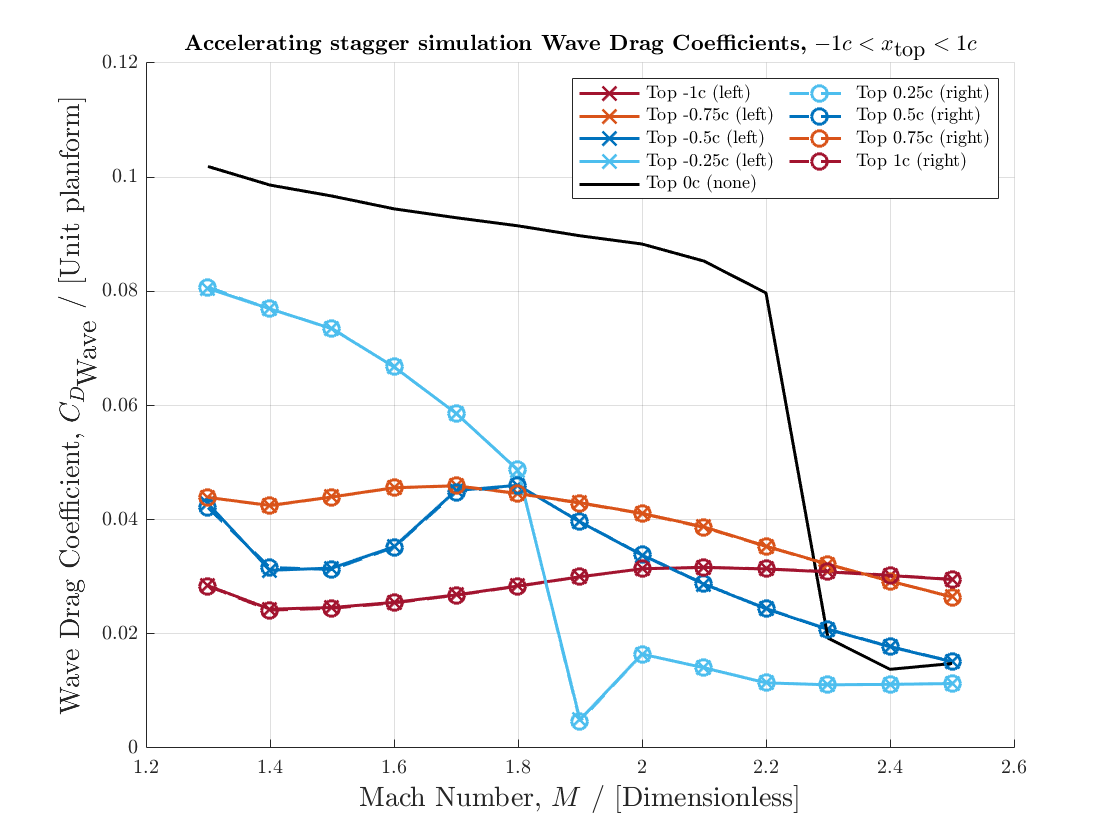

width = 1.5 ; % Line thickness
lsize = 14 ; tsize = 14 ; legsize = 12 ; msize =8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MATLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load("cd_stag_accel.mat")
load("cl_stag_accel.mat")

figure
hold on
plot(Machs,cd_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cd_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cd_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cd_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)

plot(Machs,cd_stag_accel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

plot(Machs,cd_stag_accel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
plot(Machs,cd_stag_accel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cd_stag_accel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cd_stag_accel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",red)

grid on; box off; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
legend('Top -1c (left)','Top -0.75c (left)','Top -0.5c (left)','Top -0.25c (left)','Top 0c (none)','Top 0.25c (right)','Top 0.5c (right)','Top 0.75c (right)','Top 1c (right)','NumColumns',2)
title('\textbf{Accelerating stagger simulation Wave Drag Coefficients,} $-1c<x_{\textrm{top}}<1c$')
hold off

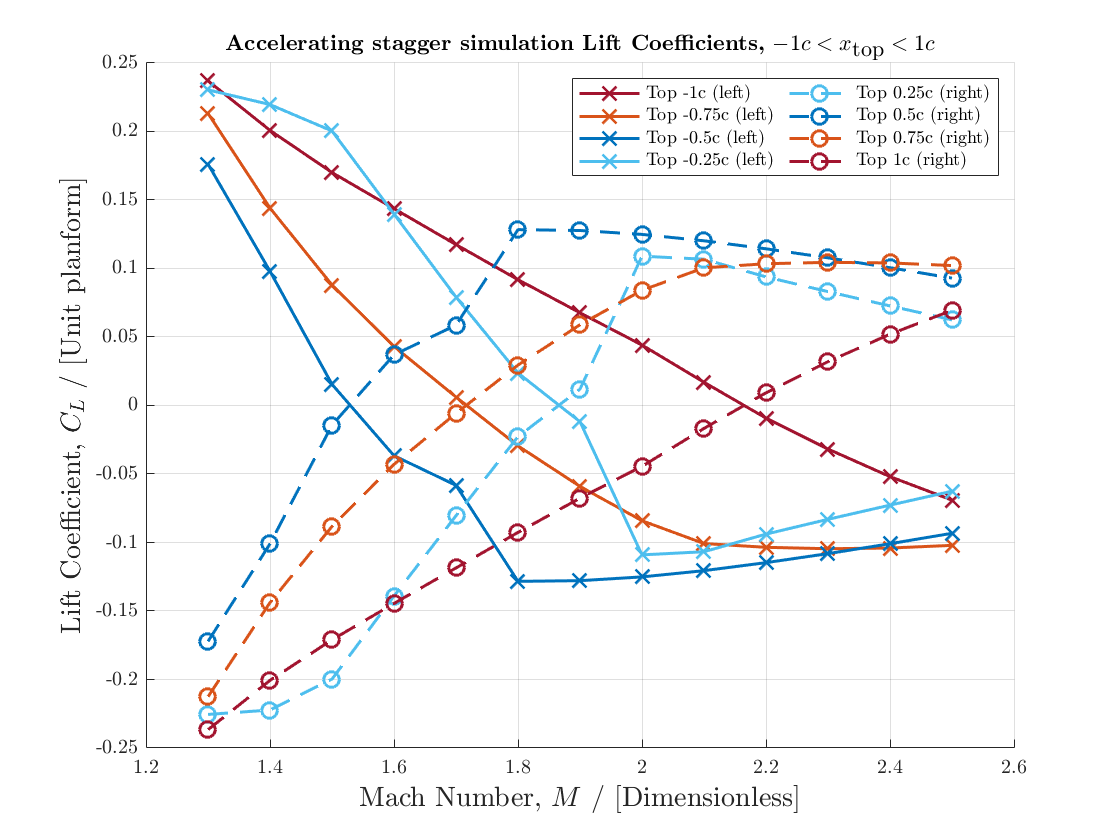


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
hold on
plot(Machs,cl_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cl_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cl_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cl_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)

plot(Machs,cl_stag_accel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
plot(Machs,cl_stag_accel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cl_stag_accel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cl_stag_accel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",red)

grid on; box off; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Lift Coefficient, $C_{L}$ / [Unit planform]",'FontSize',lsize)
legend('Top -1c (left)','Top -0.75c (left)','Top -0.5c (left)','Top -0.25c (left)','Top 0.25c (right)','Top 0.5c (right)','Top 0.75c (right)','Top 1c (right)','NumColumns',2)
title('\textbf{Accelerating stagger simulation Lift Coefficients,} $-1c<x_{\textrm{top}}<1c$')
hold off

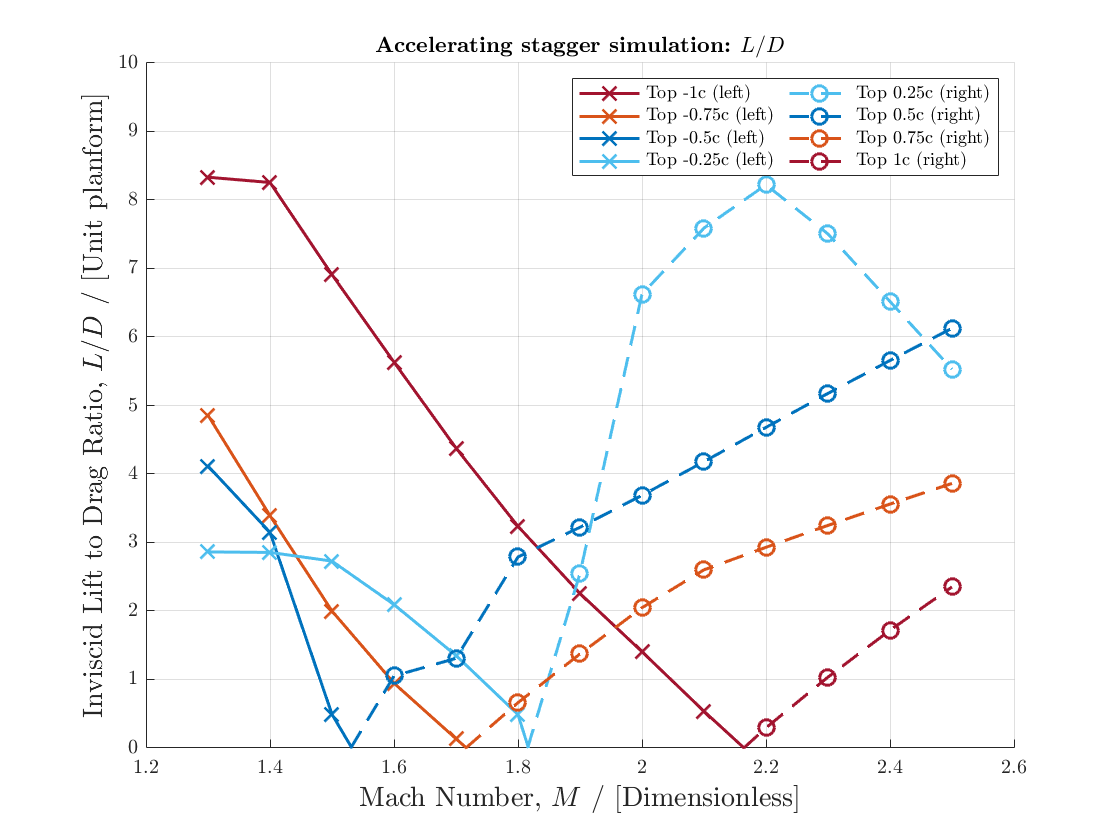


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
loverd_stag_accel = cl_stag_accel./cd_stag_accel;

figure
hold on
plot(Machs,loverd_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,loverd_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,loverd_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,loverd_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)

%plot(Machs,loverd_stag_accel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

plot(Machs,loverd_stag_accel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
plot(Machs,loverd_stag_accel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,loverd_stag_accel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,loverd_stag_accel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",red)

grid on; box off; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Inviscid Lift to Drag Ratio, $L/D$ / [Unit planform]",'FontSize',lsize)
legend('Top -1c (left)','Top -0.75c (left)','Top -0.5c (left)','Top -0.25c (left)','Top 0.25c (right)','Top 0.5c (right)','Top 0.75c (right)','Top 1c (right)','NumColumns',2)
title('\textbf{Accelerating stagger simulation:} $L/D$')
hold off
ylim([0 10])